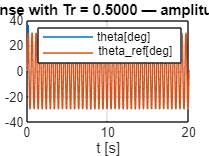

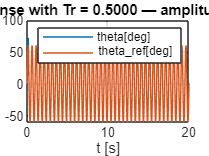

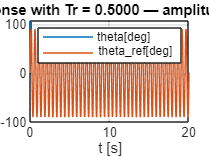

n = size(A,1);

Tr = 0.5; 

Ampl = [30, 60, 90];

omega_0 = 2*pi/Tr; 

static_friction_amplitude = mld.tausf;

% Preallocazione vettore di SimulationOutput
SimOut_2_2_6_fric = repmat(Simulink.SimulationOutput, length(Ampl), 1);

for v = 1:3
    amplitude = Ampl(v);
    alpha = [1 0 omega_0^2 0];
    m = length(alpha) - 1;
    
    Az = zeros(m+n,m+n);
    Bz = zeros(m+n,1);
    
    for i = 1:m-1
        Az(i, i+1) = 1;
    end
    
    Az(m,1:m) = -fliplr(alpha(2:end));
    Az(m,m+1:end) = C;
    
    Az(m+1:end, m+1:end) = A;
    
    Bz(end-n+1:end) = B;
    
    omega_n = 33.83;
    
    theta1 = pi/4;
    theta2 = pi/6;
    
    lambda_c1 = -omega_n*(cos(theta1) + 1j*sin(theta1));
    lambda_c2 = -omega_n*(cos(theta1) - 1j*sin(theta1));
    
    lambda_c3 = -omega_n*(cos(theta2) + 1j*sin(theta2));
    lambda_c4 = -omega_n*(cos(theta2) - 1j*sin(theta2));
    
    lambda_c5 = -omega_n;
    
    poles = [lambda_c1 lambda_c2 lambda_c3 lambda_c4 lambda_c5];
    
    Kz = place(Az, Bz, poles);
    
    k   = Kz(1:m);
    Kxi = Kz(m+1:end);
    
    num_H = fliplr(k);
    
    den_H = alpha;
    
    H = tf(num_H, den_H);

     % --- Simulazione ---
    SimOut_2_2_6_fric(v) = sim('Robust_design_sinusoidal_validation');

    theta = SimOut_2_2_6_fric(v).th.signals.values;

    time = SimOut_2_2_6_fric(v).th.time;

    theta_ref = SimOut_2_2_6_fric(v).th_ref.signals.values;

    figure;
    plot(time, theta);
    title(sprintf('Step response with Tr = %.4f — amplitude = %.0f deg', Tr, amplitude));
    grid on
    xlabel('t [s]');
    hold on
    plot(time, theta_ref);
    legend('theta[deg]','theta\_ref[deg]')
end